## Import linear model Pod elevation

pod_trav_plant = load("podTrPlant.mat");
pod_trav_plant =frd(pod_trav_plant.o2i1,pod_trav_plant.o2i1x,'FrequencyUnit','Hz');

trav_pod_model ='Pod_trav_plant_linear';
io(1)=linio('Pod_trav_plant_linear/In_engine_current',1,'input');
io(2)=linio('Pod_trav_plant_linear/MS_gyro_velocity',1,'output');
simulation_POD_trav_plant_to_gyro = linearize(trav_pod_model,io);

## bode of the original plants

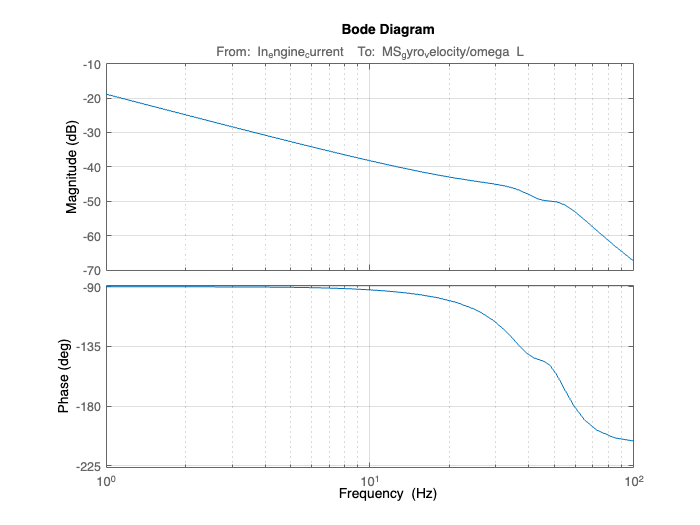

bode(simulation_POD_trav_plant_to_gyro)
grid on
xlim([1,100])

## Sisotool for notch filters and gain (external window GUI)

%sisotool(simulation_POD_trav_plant_to_gyro)

## Gain and notch

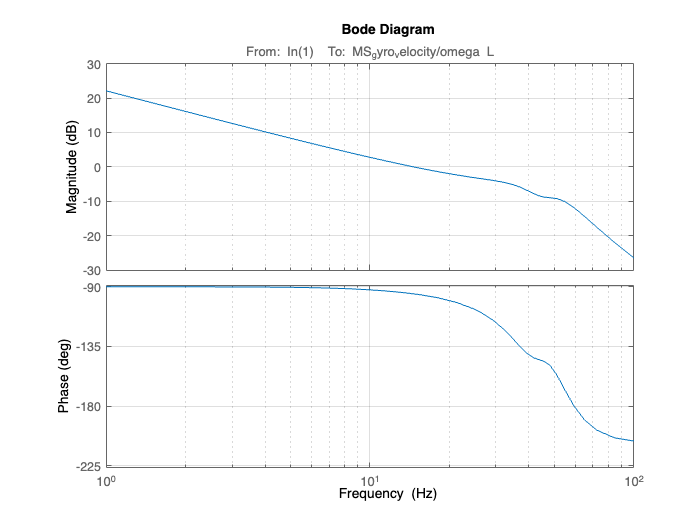

gain_pod_trav = 111.93;
bode(simulation_POD_trav_plant_to_gyro*gain_pod_trav)
grid on
xlim([1,100])

## PI tuner

opts = pidtuneOptions('PhaseMargin',50);
[C_pi_pod_trav,info] = pidtune(simulation_POD_trav_plant_to_gyro*gain_pod_trav,'PI',130,opts)

C_pi_pod_trav =
 
             1 
  Kp + Ki * ---
             s 

  with Kp = 1.13, Ki = 80.8
 
Continuous-time PI controller in parallel form.



info = struct with fields:
                Stable: 1
    CrossoverFrequency: 130
           PhaseMargin: 50.0000


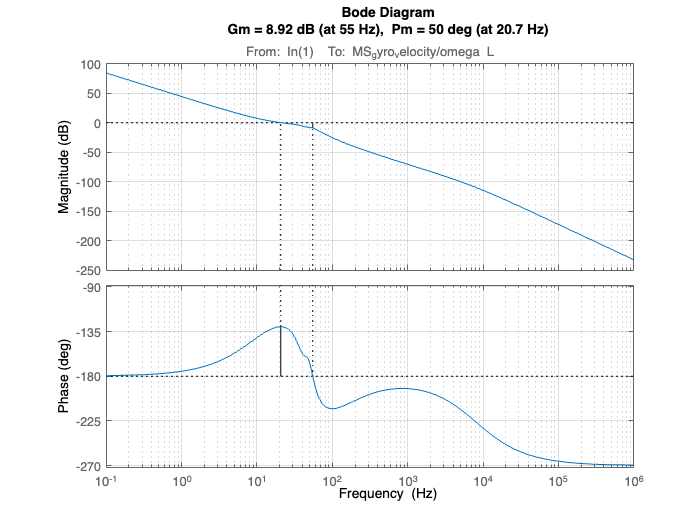

margin(simulation_POD_trav_plant_to_gyro*gain_pod_trav*C_pi_pod_trav)
grid on

## Saved results load

% margin(simulation_POD_trav_plant_to_gyro*gain_pod_trav*C_pi_pod_trav)
% xlim([1,100])
% grid on

## Define transfer function

% gain_notch_pod_elev_tf=tf(Notch_gain_POD_elev)
C_pi_pod_trav_Kp=C_pi_pod_trav.Kp+0.1;
C_pi_pod_trav_Ki=C_pi_pod_trav.Ki-20;